**Purpose**: Incorporate spike-timing-dependent plasticity (STDP learning) into any of your DynaSim spiking models.

STDP can be incorporated into any type of Dynasim connection mechanism between any two populations of neurons. There are four different mechanisms according to STDP type: 'STDP_standard', 'STDP_antiHebbian', 'STDP_potentiation', and 'STDP_depression'.

We used the "online implementation" of STDP model with soft bounds as described here: [http://www.scholarpedia.org/article/Spike-timing_dependent_plasticity#Online_implementation_of_STDP_models](http://www.scholarpedia.org/article/Spike-timing_dependent_plasticity#Online_implementation_of_STDP_models)

The tutorial illustrates the four types of STDP learning.

close all;

t_post = 100:5:300;
t_pre = 200;

delta_t = nan(size(t_post));
delta_w = nan(size(t_post));

% Choose among these four different built-in STDP types

% STDP_type = 'standard';
% STDP_type = 'antiHebbian';
% STDP_type = 'potentiation';
% STDP_type = 'depression';

STDP_type = 'standard'

STDP_type = 'standard'

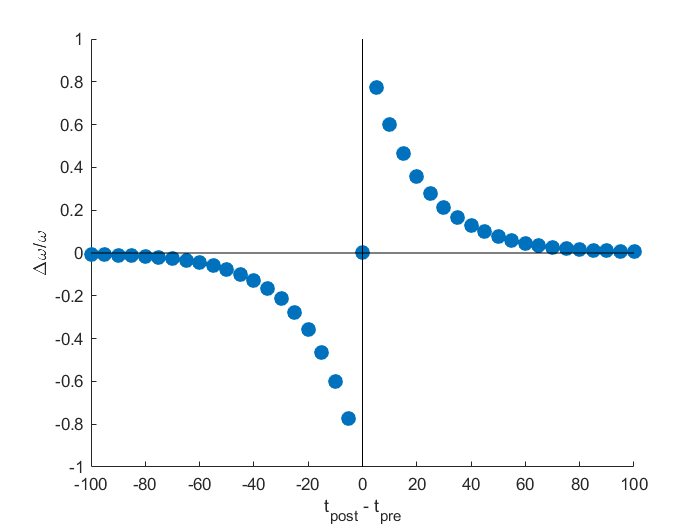


eqns = {
        'dV/dt= 0; V(0)=-65' % define voltage dynamics and initial conditions
        'monitor V.spikes(0)'           % monitor spikes
       };

spec = [];
spec.populations(1).name = 'E1';
spec.populations(1).size = 1;
spec.populations(1).equations = eqns;
spec.populations(2).name = 'E2';
spec.populations(2).size = 1;
spec.populations(2).equations = eqns;
spec.connections(1).direction = 'E1->E2';
spec.connections(1).mechanism_list = ['STDP_',STDP_type];

for iSim=1:numel(t_post)
    spec.connections(1).parameters = {'tspk_post',t_post(iSim)*ones(1,spec.populations(2).size),'tspk_pre',t_pre*ones(1,spec.populations(1).size)};
    data = dsSimulate(spec,'tspan',[0 400],'dt',1,'solver','euler'); % right now DynaSim only supports STDP with the euler solver
    delta_t(iSim) = t_post(iSim) - t_pre;
    eval(['w = data.E2_E1_STDP_', STDP_type,'_w;']);
%     % Uncomment this if you want to inspect w, x, and y for the most interesting simulations
%     if ismember(iSim,0.5*(numel(t_post)-1)+[0,1,2])
%         eval(['x = data.E2_E1_STDP_', STDP_type,'_x;']);
%         eval(['y = data.E2_E1_STDP_', STDP_type,'_y;']);
%         figure
%         subplot(3,1,1)
%         plot(w,'.-')
%         subplot(3,1,2)
%         plot(x,'.-')
%         subplot(3,1,3)
%         plot(y,'.-')
%         drawnow
%     end
    dt = data.time(2)-data.time(1);
    % the index of the rightmost spike is:
    % +1, because arrays in Matlab start at position 1
    % +1, because in DynaSim t=0 is set at second position (ICs occupy the first position)
    idx = round(max([t_pre, t_post(iSim)])/dt)+2;
    % from this point, w is further shifted:
    % +1, as the monitor of spikes operates after the update of state variables (hence spikes won't be seen until next dt)
    % +1, since w(n) depends on {x,y} at n-1, so there is another extra dt here
    delta_w(iSim) = (w(idx+2,1,1) - w(idx+1,1,1))/w(idx+1,1,1); 
end

figure
scatter(delta_t, delta_w, 80, 'filled')
hold on
plot([-100 100],[0 0],'k-')
plot([0 0],[-1 1],'k-')
xlabel('t_{post} - t_{pre}')
ylabel('\Delta\omega/\omega')

We now demonstrate how to use these STDP mechanisms in a simple model with two HH-type neurons (E1 and E2). The last plot that the script generates shows how the synaptic weight changes after each spike from E1 to E2.

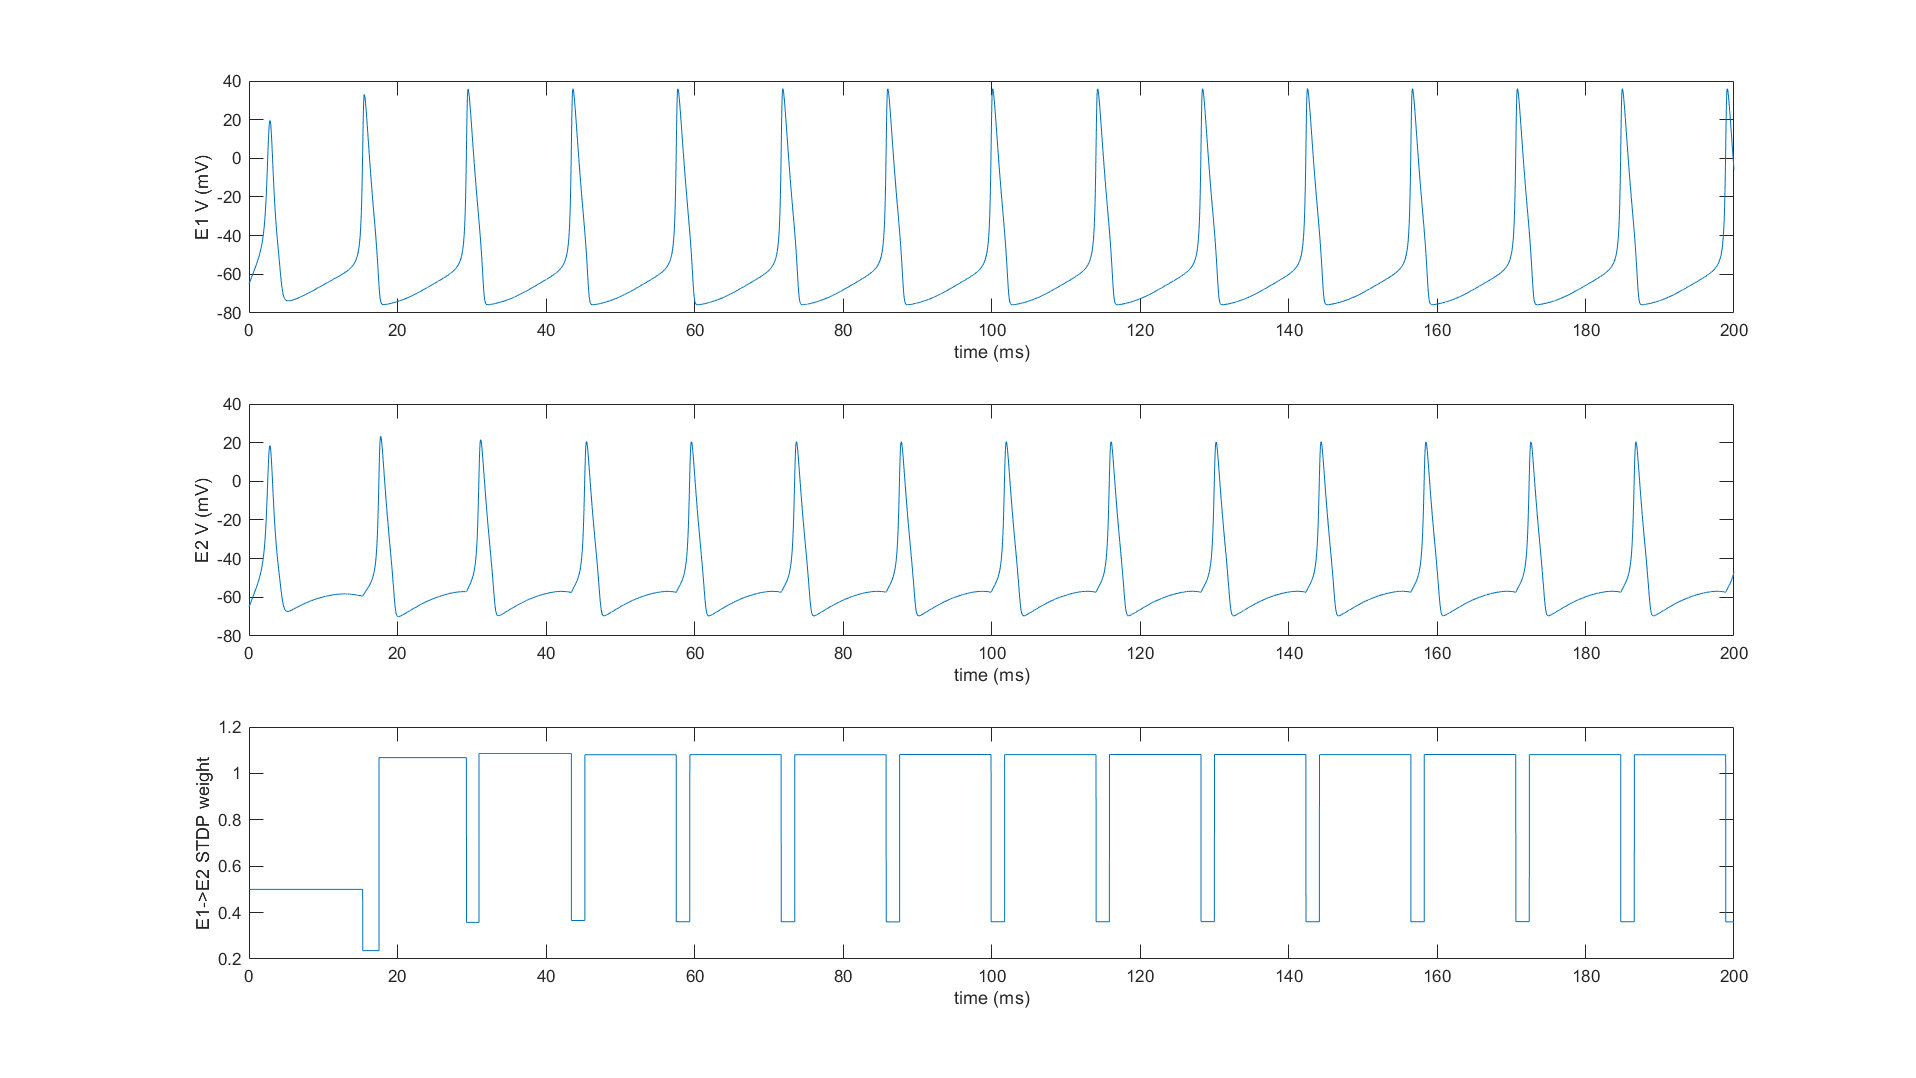

% Define neuron equations
eqns = {
        'dV/dt= I + @current; V(0)=-65' % define voltage dynamics and initial conditions
        '{iNa,iK}'                      % add Na+ and K+ mechanisms to neuron (i.e., insert INa and IK into @current)
        'I=10'                          % set tonic drive parameter
        'monitor V.spikes(0)'           % monitor spikes
       };
% Define network with two neurons connected by plastic synapse
spec = [];
spec.populations(1).name = 'E1';
spec.populations(1).equations = eqns;
spec.populations(2).name = 'E2';
spec.populations(2).equations = eqns;
spec.connections(1).direction = 'E1->E2';         % add synapse from E1 to E2
spec.connections(1).mechanism_list = {'STDP_Isyn', ['STDP_',STDP_type]}; % using one of the built-in STDP mechanisms

% Simulate model
data = dsSimulate(spec,'tspan',[0 200],'solver','euler'); % right now DynaSim only supports STDP with the euler solver

% Plot changes in synaptic weights
figure('units','normalized','position',[0 0 1 1])
subplot(3,1,1); plot(data.time, data.E1_V); % E1 voltage dynamics (spiking)
xlabel('time (ms)'); ylabel('E1 V (mV)');
subplot(3,1,2); plot(data.time, data.E2_V); % E2 voltage dynamics (spiking)
xlabel('time (ms)'); ylabel('E2 V (mV)');
subplot(3,1,3); eval(['plot(data.time, data.E2_E1_STDP_',STDP_type,'_w)']); % weight changes
xlabel('time (ms)'); ylabel('E1->E2 STDP weight');